close all;clear; clc;

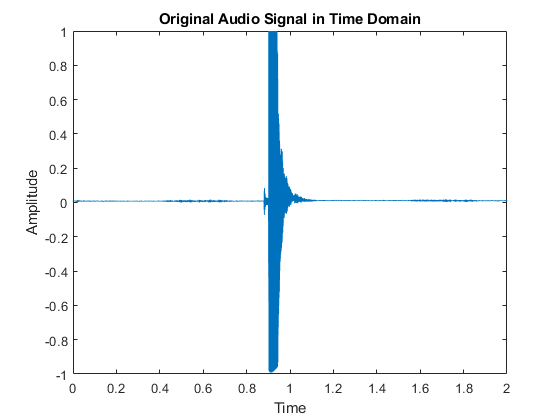

% Read the WAV file
[y, fs] = audioread('input/Sample 01.wav');
N = length(y);
tx = linspace(0, N/fs, N);


figure; 
plot(tx, y);
xlabel("Time"); ylabel("Amplitude");
title("Original Audio Signal in Time Domain");

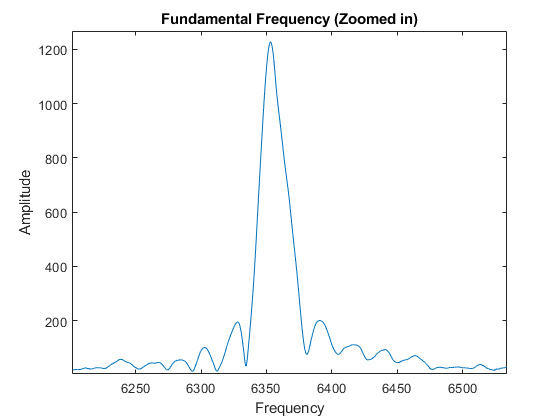

% Compute FFT
fx = linspace(0, fs, N);
Y = fft(y);

figure; 
plot(fx(1:N/2), abs(Y(1:N/2)));
xlabel("Frequency"); ylabel("Amplitude");
title("Fundamental Frequency (Zoomed in)");

xlim([6202 6534])
ylim([4 1267])

[~, indexOfMaxValue] = max(Y);
fundamental_frequency = fx(indexOfMaxValue);
disp(['Fundamental Frequency: ', num2str(fundamental_frequency), ' Hz']);

Fundamental Frequency: 6353.072 Hz


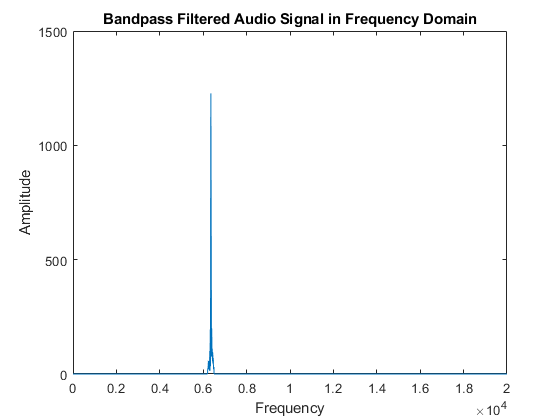

% Applying the bandpass filter
Y_cbandpass = zeros(size(Y));
cutoffLower = 6200;
cutoffUpper = 6500;
for i = 1:N
    if cutoffLower < fx(i) &&  fx(i) < cutoffUpper
        Y_cbandpass(i) = Y(i);
    else
        Y_cbandpass(i) = 0;
    end   
end


% Plot the filtered signal in the frequency domain
figure; 
plot(fx(1:N/2), abs(Y_cbandpass(1:N/2)));
xlim([0 20000]); ylim([0 1500]); 
xlabel("Frequency"); ylabel("Amplitude");
title("Bandpass Filtered Audio Signal in Frequency Domain");

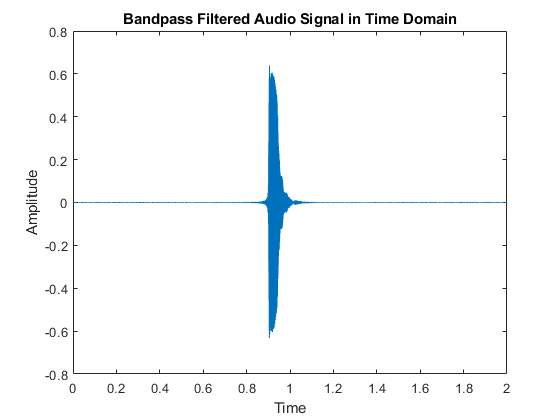

% Apply IFFT
y_cbandstop = ifft(Y_cbandpass);
figure; plot(tx, real(y_cbandstop));
xlabel("Time"); ylabel("Amplitude");
title("Bandpass Filtered Audio Signal in Time Domain");